# A Basic Introduction into MATLAB

## Simple Arithmetic

How to enter numbers, vectors and matrices, and basic arithmetic.

The basic data type in MATLAB is an n-dimensional (primarily 2-dimensional) array of double-precision numbers. They are written as sequences of numbers surrounded by brackets. Elements of a matrix can be separated by spaces, tabs, and commas in rows. Semicolons and end of lines separate lines of matrices. First, let us enter two vectors - a row vector `x` and a column vector `y`. By multiplying `x` and `y` we obtain a matrix.

x=[2,3 4]

x =      2     3     4


y=[1;2]

y =      1
     2


z=y*x

z =      2     3     4
     4     6     8


Entering a matrix

- on a single line, or

- on multiple lines

A=[2.3  4.8 9.2; 21.34 1.3e12 9]

A = 	1.0e+12 *

    0.0000    0.0000    0.0000
    0.0000    1.3000    0.0000


When MATLAB displays the matrix `A`, it prints a common coefficient `1.0e+012`` *` in the front of the matrix. All entries in the following matrix must be multiplied by this coefficient.

B = [ 1 9 23
        21 2 1
        9 11 99]

B =      1     9    23
    21     2     1
     9    11    99


Scalars are matrices of size `1x1`

a = 3.1

a = 3.1000

u = a*z

u =     6.2000    9.3000   12.4000
   12.4000   18.6000   24.8000


In names, MATLAB distinguishes between lowercase and uppercase letters. Variables are not declared but arise by an assignment. The list of currently defined variables can be obtained using a command `who`

who


Your variables are:

A  B  a  u  x  y  z  



More details about defined variable prints the function `whos` or the window **Workspace** in MATLAB IDE

whos

  Name      Size            Bytes  Class     Attributes

  A         2x3                48  double              
  B         3x3                72  double              
  a         1x1                 8  double              
  u         2x3                48  double              
  x         1x3                24  double              
  y         2x1                16  double              
  z         2x3                48  double              



Arithmetic in MATLAB is "robust"

infinity = a/0

infinity = Inf

zero = 1 / infinity

zero = 0

WhatIsThis = infinity / infinity

WhatIsThis = NaN

'NaN' is an abbreviation of "Not a Number".

MATLAB can take square roots also form negative numbers

sqrt(-1)

ans = 0.0000 + 1.0000i

MATLAB computes naturally with complex numbers. The imaginary unit can be denoted as `i` or `j`

(1+2i)*(1-2j)

ans = 5

MATLAB is a powerful calculator. The value of the last evaluated expression not assigned to any variable is stored in the variable `ans`

2^3

ans = 8

2^4

ans = 16

2^100

ans = 1.2677e+30

20^3-3*23/8

ans = 7.9914e+03

sqrt(ans)

ans = 89.3945

MATLAB knows many arithmetic, goniometric and other functions:

sin(4)

ans = -0.7568

sin(3*pi)+cos(1.23)^2

ans = 0.1117

log(2430)

ans = 7.7956

What is the base for the logarithm function `log`? The help gives us the relevant information

help log

 log    Natural logarithm.
    log(X) is the natural logarithm of the elements of X.
    Complex results are produced if X is not positive.
 
    See also log1p, log2, log10, exp, logm, reallog.

    Documentation for log
    Other functions named log



Better hypertext help can be obtained from the menu behind the button with a question mark within a blue circle. Another help with functions is provided by the button marked by *fx* within the left margin of the **Command Window** of IDE. Further possibilities are demo-videos and demo-examples.

<<HelpImg.jpg>>

## Matrix operations

Standard matrix operations but also **matrix division**!

**Standard Matrix Operations**

An expression followed by the semicolon ';' is evaluated but the result is not displayed. Addition, subtraction

A = [1 2 3; 2 3 1; 0 7 3];
B = [1 1 1; 3 2 1; 7 6 5];
C = [3 3; 3 3; 4 3];
whos

  Name            Size            Bytes  Class     Attributes

  A               3x3                72  double              
  B               3x3                72  double              
  C               3x2                48  double              
  WhatIsThis      1x1                 8  double              
  a               1x1                 8  double              
  ans             1x1                 8  double              
  infinity        1x1                 8  double              
  u               2x3                48  double              
  x               1x3                24  double              
  y               2x1                16  double              
  z               2x3                48  double              
  zero            1x1                 8  double              



A+B

ans =      2     3     4
     5     5     2
     7    13     8


A-B

ans =      0     1     2
    -1     1     0
    -7     1    -2


The command `A+C` triggers an error message

That is why it is not executed in this script.

Matrix multiplication:

D = A*C

D =     21    18
    19    18
    33    30


A*B

ans =     28    23    18
    18    14    10
    42    32    22


B

B =      1     1     1
     3     2     1
     7     6     5


A multiplication by a scalar value:

3*B

ans =      3     3     3
     9     6     3
    21    18    15


Multiplying only the corresponding components `.*`:

A.*B

ans =      1     2     3
     6     6     1
     0    42    15


**Matrix transpose**

For a matrix of real values `A`, the expression `A'` returns the transpose of `A`.

A = [ 1 2 3; 4 5 6]

A =      1     2     3
     4     5     6


A'

ans =      1     4
     2     5
     3     6


Actually, `A'` is the complex conjugate transpose of `A`, i.e. if `A` is complex with non-zero imaginary part, then the matrix `A'` is not only transposed but all imaginary parts of all components have sign opposite to the corresponding component of `A`.

B = A+1i*(rand(2,3)-0.5)

B =    1.0000 + 0.3147i   2.0000 - 0.3730i   3.0000 + 0.1324i
   4.0000 + 0.4058i   5.0000 + 0.4134i   6.0000 - 0.4025i


B'

ans =    1.0000 - 0.3147i   4.0000 - 0.4058i
   2.0000 + 0.3730i   5.0000 - 0.4134i
   3.0000 - 0.1324i   6.0000 + 0.4025i


In case we would like to obtain 'plain' transpose for a complex matrix, we must precede the apostrophe by a dot:

B.'

ans =    1.0000 + 0.3147i   4.0000 + 0.4058i
   2.0000 - 0.3730i   5.0000 + 0.4134i
   3.0000 + 0.1324i   6.0000 - 0.4025i


**Functions Generating Matrices**

`zeros(m,n)` is a zero matrix of size *mxn*

zeros(2,3)

ans =      0     0     0
     0     0     0


`ones(m,n)` is a matrix of size *mxn* containing ones only.

ones(2,3)

ans =      1     1     1
     1     1     1


What vector or matrix we obtain by calling `ones(4)`?

`eye(n)` is the identity matrix of size *nxn*

eye(3)

ans =      1     0     0
     0     1     0
     0     0     1


`diag(v)` constructs a diagonal matrix which is zero except its diagonal that contains values from the vector `v`.

diag([1,2,3])

ans =      1     0     0
     0     2     0
     0     0     3


**Solving systems of linear equations by "matrix division"**

If a matrix *A* is not singular, then the system of equations


$$Ax=b$$


has a solution


$$x=A^{-1}b$$


In MATLAB we use the backslash as an operator of "division from the left". At first, we generate a random matrix `A`

A=rand(3,3)

A =     0.1419    0.7922    0.0357
    0.4218    0.9595    0.8491
    0.9157    0.6557    0.9340


and a random vector `b`

b=rand(3,1)

b =     0.6787
    0.7577
    0.7431


Then we solve the system 


$$Ax=b:$$


  x = inv(A)b ... there is backslash which represent inversion

x=A\b

x =     0.4896
    0.7795
   -0.2316


x=inv(A)*b

x =     0.4896
    0.7795
   -0.2316


We can validate the result (obtained by a numeric method):

A*x-b

ans = 	1.0e+-15 *

    0.1110
    0.3331
    0.4441


## How to Generate Vectors

For various purposes, we will need vectors with arithmetic and other sequences.

The growing sequence of integers between `A` and `B` can be generated as `A:B`

t = 1:6

t =      1     2     3     4     5     6


This is an arithmetic sequence with the step of size 1 but the size of the step can be arbitrary. The sequence from `A` to `B` with step of size `Step` we get as `A:Step:B`

t=-1:0.2:1

t =    -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000    1.0000


Even negative steps are possible

t = 20:-3:1

t =     20    17    14    11     8     5     2


Similarly, the function `linspace(A,B,N)` returns `N` numbers which divide the interval


$$<A,B>$$


into `N-1` segments of equal size.

linspace(0,1,11)

ans =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


The logarithmic sequence between `10^A` and `10^B` is produced by the function `logspace(A,B,N)`

logspace(1,6,7)

ans = 	1.0e+06 *

    0.0000    0.0001    0.0005    0.0032    0.0215    0.1468    1.0000


## Vectorized Functions

Whenever possible, each function in MATLAB is so-called vectorized. This means that the argument of the function can be a vector (or a matrix) and the function returns another vector (or matrix) of the same size whose entries are the function values of the entries of the original argument. E.g. the table of the function *sin(2t)* on the interval


$$ <0 ,\pi>$$


 t = 0:0.1:pi

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000


is obtained as

tab = sin(2*t)

tab =          0    0.1987    0.3894    0.5646    0.7174    0.8415    0.9320    0.9854    0.9996    0.9738    0.9093    0.8085    0.6755    0.5155    0.3350    0.1411   -0.0584   -0.2555   -0.4425   -0.6119   -0.7568   -0.8716   -0.9516   -0.9937   -0.9962   -0.9589   -0.8835   -0.7728   -0.6313   -0.4646   -0.2794   -0.0831


We can plot easily a graph of this function

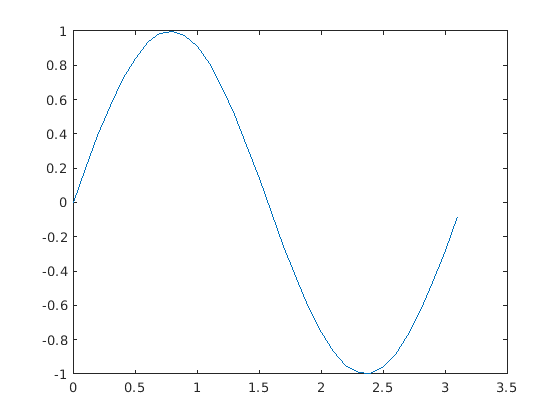

plot(t,tab)

Be careful with multiplication and division. Usually, we want to compute a function for each entry of an array. Example: We want to draw a graph of the function


$$1/(1+x^2)$$


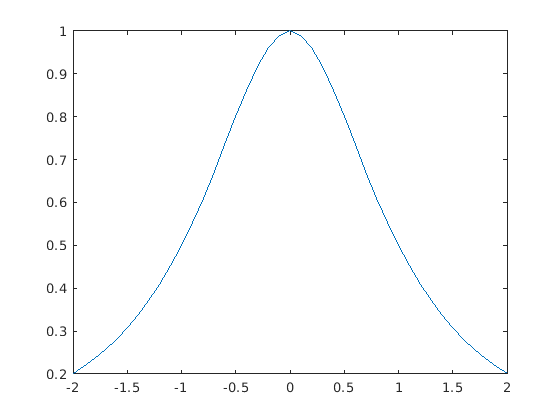

x = -2:0.1:2;
y = 1./(1+x.^2);
plot(x,y)

## Function Plotting

MATLAB enables us to draw both 2D and 3D graphs. We have already seen the plotting of a 2D graph with the function `plot(x,y)`. This function accepts also a third parameter. The third parameter specifies the parameters of the drawing. E.g. the color of the graph - the red color:

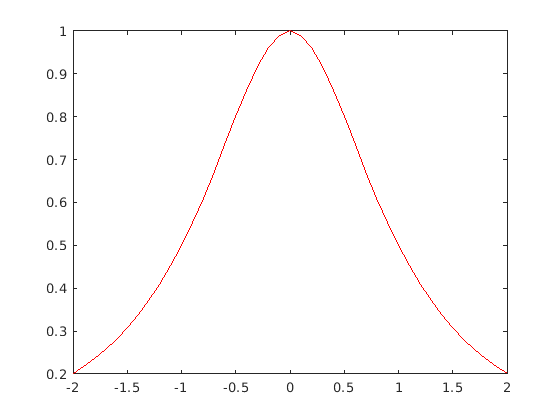

plot(x,y,'r')

For a green graph with a dashed line:

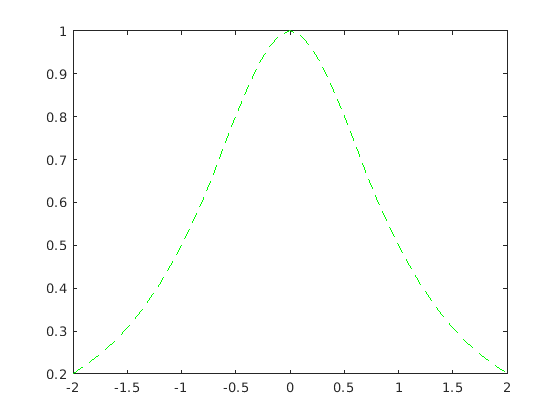

plot(x,y,'g--')

Without connecting the depicted points. Points as little circles:

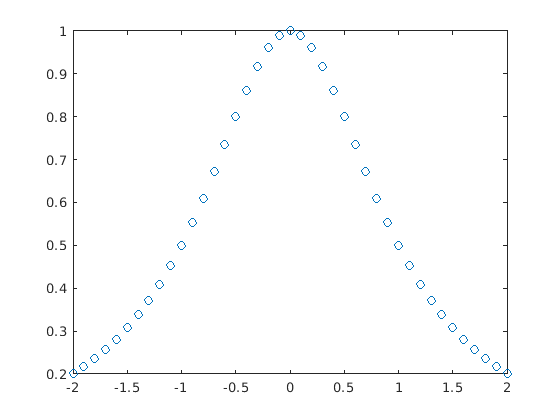

plot(x,y,'o')

Without connecting the depicted points. Points as little crosses:

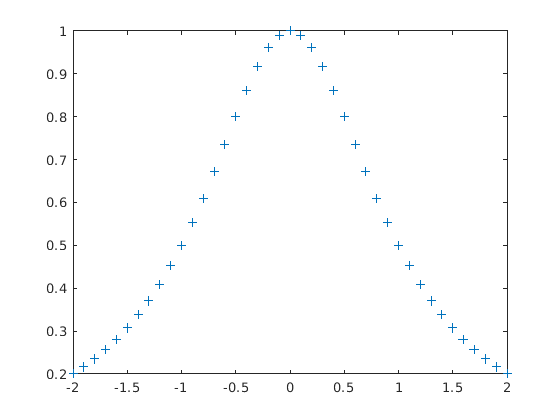

plot(x,y,'+')

For further possibilities see the help for `plot`.

It is possible to label the graph. `xlabel('string')` and `ylabel('string')` change the labels of the x- and y-axes in the graph.

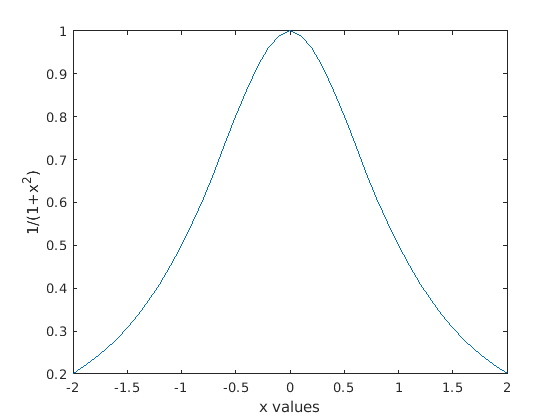

plot(x,y)
xlabel('x values');
ylabel('1/(1+x^2)');

`grid` adds a rectangular grid to the plot. `hold on` "holds" the current graph and enables to add more graphs into the already drawn one

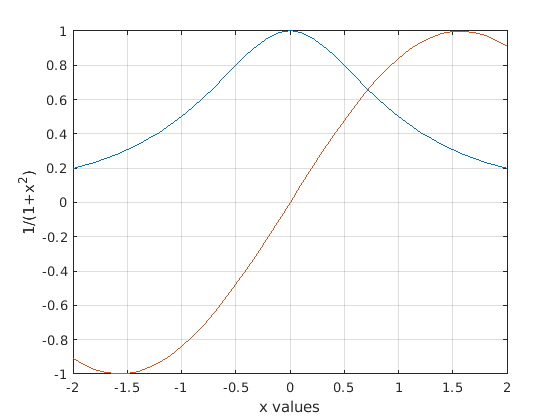

hold on
grid
plot(x,sin(x))

`hold off` stops "holding" of the graph.

hold off

More than one graph can be plotted also by increasing the number of parameters in the call to `plot`.

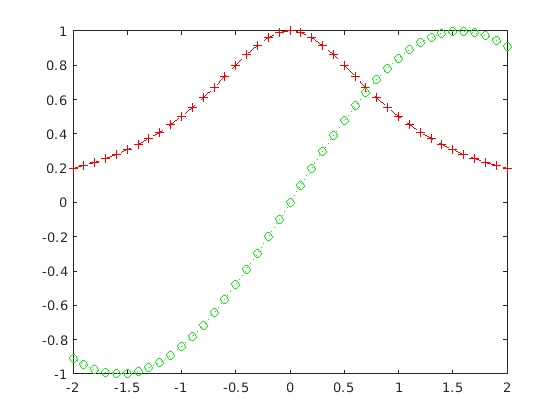

plot(x,y,'r+--',x,sin(x),'go:')

## Some Miscellaneous Functions

The function `max(x)` returns maximal element if `x` is a vector, or a vector of maximal elements in each column if `x` is a matrix. Further possibilities for calling `max` are described within the help.

max([2, -33.1,14,9])

ans = 14

A

A =     0.1419    0.7922    0.0357
    0.4218    0.9595    0.8491
    0.9157    0.6557    0.9340


max(A)

ans =     0.9157    0.9595    0.9340


 [argvalue, argmax] = max(A)

argvalue =     0.9157    0.9595    0.9340


argmax =      3     2     3


 argmax

argmax =      3     2     3


The function `min(x)` works similarly.

`abs(x)` computes absolute value of entries of `x`.

abs([1, -3,-4, 2])

ans =      1     3     4     2


`size(x)` returns a vector with sizes of `x` in each dimension.

D = randn(2,3)

D =    -0.3034   -0.7873   -1.1471
    0.2939    0.8884   -1.0689


size(D)

ans =      2     3


`length(x)` yields "length" of the array `x`, i.e. `max(size(x))`.

length(D)

ans = 3

`save fname` saves the values of all currently defined variables into the file with the name `fname.mat`

`save fname var1 var2` saves only the values of the specified variables to the file `fname.mat`

`load fname` reads and restores values of all variables from the file `fname.mat`.

`quit` ends MATLAB.

## Working with Elements of Matrices

C = [1 2; 3 4; 5 6]

C =      1     2
     3     4
     5     6


Accessing a single entry in a matrix

C(2,1)

ans = 3

The whole second row of matrix `C`

C(2,:)

ans =      3     4


The second and the third row of the matrix `C`

C(2:3,:)

ans =      3     4
     5     6


The first column of matrix `C`

C(:,1)

ans =      1
     3
     5


Selecting entries from a vector

x=0:2:14

x =      0     2     4     6     8    10    12    14


idx = [ 3 1 4];
x(idx)

ans =      4     0     6


Indexing by a vector can be used also for changing entries of a matrix (or vector)

x(idx)=[1,2,3]

x =      2     2     1     3     8    10    12    14


## Formatting Output

By default, MATLAB prints numbers with limited accuracy (5 digits) and often it inserts empty lines between lines of output. This can be changed. A higher number of displayed digits we get after the following command

format long
A

A =    0.141886338627215   0.792207329559554   0.035711678574190
   0.421761282626275   0.959492426392903   0.849129305868777
   0.915735525189067   0.655740699156587   0.933993247757551


It is possible to force a format with exponent (floating-point format)

format long e
A

A =      1.418863386272153e-01     7.922073295595544e-01     3.571167857418955e-02
     4.217612826262750e-01     9.594924263929030e-01     8.491293058687771e-01
     9.157355251890671e-01     6.557406991565868e-01     9.339932477575505e-01


Another combination is short format with forced exponent

format short e
A

A =    1.4189e-01   7.9221e-01   3.5712e-02
   4.2176e-01   9.5949e-01   8.4913e-01
   9.1574e-01   6.5574e-01   9.3399e-01


Or the short format without forced floating point format. Nevertheless, if necessary, the floating point format will be used, otherwise the fixed point format is used

format short
A

A =     0.1419    0.7922    0.0357
    0.4218    0.9595    0.8491
    0.9157    0.6557    0.9340


One of the most useful settings is the following command which suppresses unnecessary empty lines in output by which the out becomes more "compact".

format compact
A

A =     0.1419    0.7922    0.0357
    0.4218    0.9595    0.8491
    0.9157    0.6557    0.9340


## Further Commands and Options

will be shown during the next lab

- programming with MATLAB,

- sparse matrices,

- structures,

- cell arrays.